# Sistemas de Control II - FCEFyN (UNC)

## Caso de estudio 2 - Motor (Actividad 1.5)

clear all; close all; clc;

data= readtable('../Resources/Curvas_Medidas_Motor_2025_v.xls');
data;
% Convert table to array. Apply transpose.
dataT= table2array(data);

% Obtain time(t).
t      = dataT(:,1);
wr     = dataT(:,2);
ia     = dataT(:,3);
v      = dataT(:,4);
torque = dataT(:,5);

Plot measurements

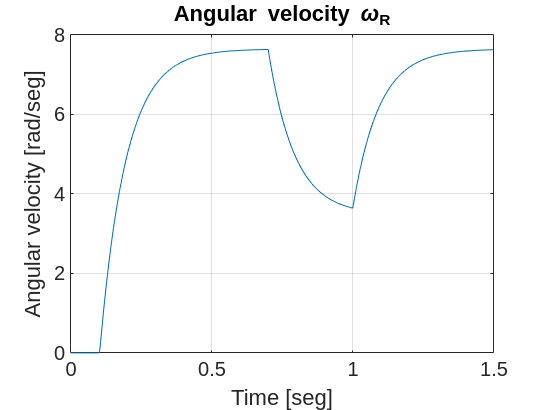

figure(1); plot(t, wr); title('Angular velocity \omega_{R}'); 
ylabel('Angular velocity [rad/seg]'); xlabel('Time [seg]');
grid on; %xlim([0, 0.7]);

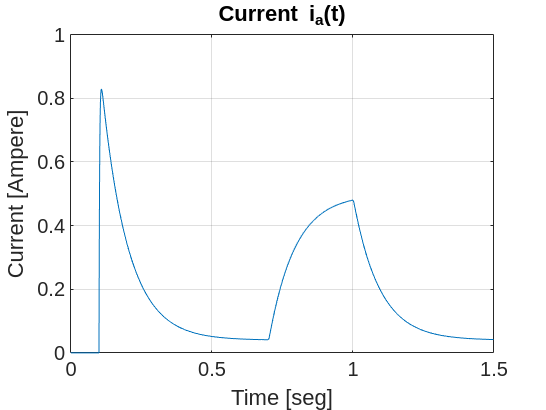

figure(2); plot(t, ia); title('Current i_{a}(t)'); 
ylabel('Current [Ampere]'); xlabel('Time [seg]');
grid on;

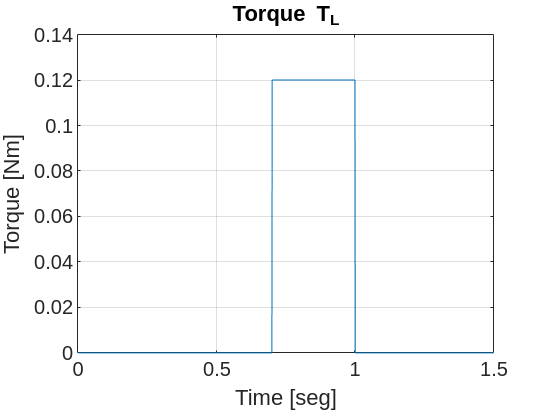

figure(3); plot(t, torque); title('Torque T_{L}'); 
ylabel('Torque [Nm]'); xlabel('Time [seg]');
grid on; ylim([0, 0.14]);

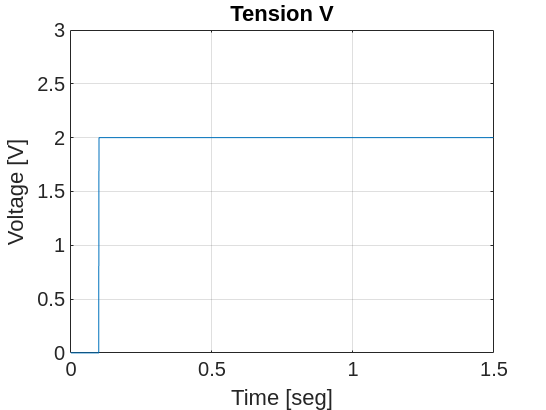

figure(4); plot(t, v); title('Tension V'); 
ylabel('Voltage [V]'); xlabel('Time [seg]');
grid on; ylim([0, 3])

Apply Chen Method to $$ Angular \, velocity \, (\omega_{R}) $$

Transfer Function $$ \frac{ \omega_{R} }{ V_{a} } = \frac{\mathrm{Ki}}{J\,\mathrm{Laa}\,\left(s^2+\frac{\mathrm{Laa}\,\left(\mathrm{Bm}\,\mathrm{Ra}+\mathrm{Ki}\,\mathrm{Km}\right)}{J}+\frac{s\,\left(\mathrm{Bm}\,\mathrm{Laa}+J\,\mathrm{Ra}\right)}{J}\right)} $  $

K= max(wr)

K = 7.6247

stepAmplitude= max(v)

stepAmplitude = 2


%i= 155;
%h= 60;

i= 111;
h= 10;

%t1 = t(i);
%y1 = wr(i)
%t2 = t(i+h);
%y2 = wr(i+h)
%t3 = t(i+2*h);
%y3 = wr(i+2*h)

t1 = t(i);
y1 = wr(i)

y1 = 0.5954

t2 = t(2*i);
y2 = wr(2*i)

y2 = 5.5165

t3 = t(3*i);
y3 = wr(3*i)

y3 = 6.9985


deltaTime= t2-t1

deltaTime = 0.1110

delayTime= 0.102;


TF= minreal(chenMethod(y1, y2, y3, K, stepAmplitude, deltaTime, delayTime, t1, 0));

T1_e = 0.0004 + 0.0028i

T2_e = 0.0760

disp('Transfer Function: ')

Transfer Function: 


TF


TF =
 
                             (2332-1.75e04i)
  exp(-0.102*s) * --------------------------------------
                  s^2 + (59.66-349.1i) s + (611.7-4590i)
 
Continuous-time transfer function.
Model Properties



disp('Poles and zeros: ')

Poles and zeros: 


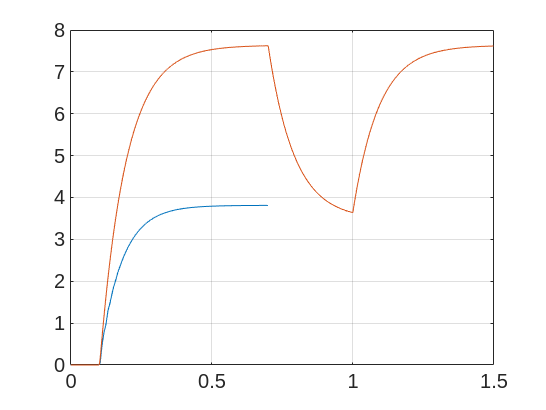

pole(TF);
zero(TF);

figure(4);
[ys, ts]= step(TF, 0.7);
figure(5);
plot(ts, ys, t, wr); grid on;

Apply Chen Method to $$ Torque \, (T_{L}) $$

Transfer Function $$ \frac{ \omega_{R} }{ T_{L}} = -\frac{\frac{s}{J}+\frac{\mathrm{Ra}}{J\,\mathrm{Laa}}}{s^2+\frac{\mathrm{Bm}\,\mathrm{Ra}+\mathrm{Ki}\,\mathrm{Km}}{J\,\mathrm{Laa}}+\frac{s\,\left(\mathrm{Bm}\,\mathrm{Laa}+J\,\mathrm{Ra}\right)}{J\,\mathrm{Laa}}}$$

t_tl = t(701:end, 1);
%size(t(701:end, 1))
%size(t, 1)
wr_tl= wr(701:end, 1);
min(wr_tl)

ans = 3.6380

max(wr_tl)

ans = 7.6247

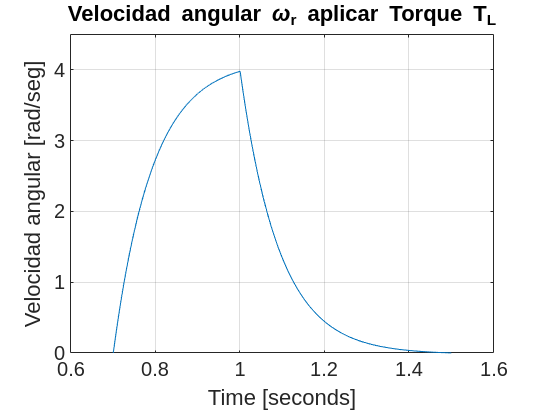

for i=1: length(t_tl)
    wr_tl(i)= (wr_tl(i)-max(wr_tl))*(-1);
end

%% Generate .csv to new data [t_tl, wr_tl]. 
filename= 'Generated Data/dataTL.csv';
headers= {'Time [Seconds]', 'Torque [Nm]'};
fi= fopen(filename, 'w');
fprintf(fi, '%s,%s\n', headers{:});
fclose(fi);
writematrix([t_tl, wr_tl], filename, 'WriteMode', 'append');

plot(t_tl, wr_tl);
ylim([0, 4.5]); grid on; title('Velocidad angular \omega_{r} aplicar Torque T_{L}');
xlabel('Time [seconds]'); ylabel('Velocidad angular [rad/seg]');


% Apply Chen's method (Second-Order Systems with differents poles).